# Controlling the separator level

clear

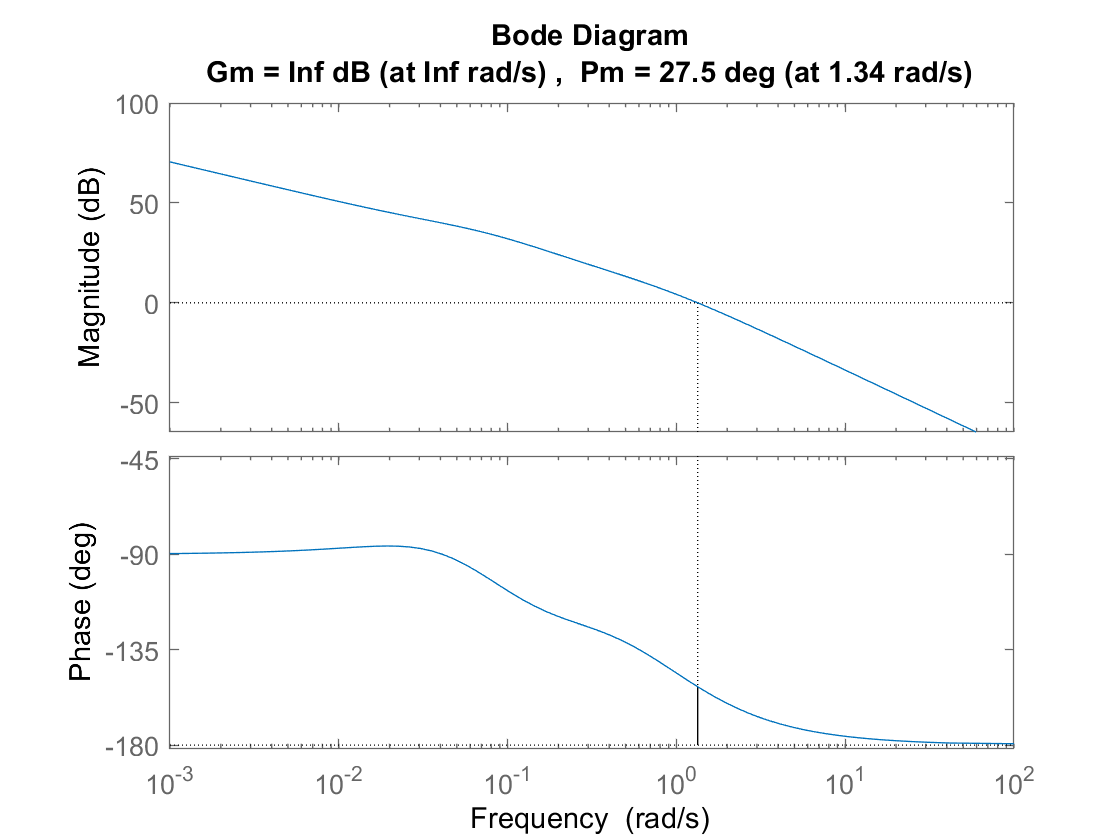

% The internal states are ordered:
% P2, X2, P100 lag, L2, F200 lag, F2 lag
x_op = [50.5, 25, 194.7, 1, 208, 2];

% The inputs are orderes:
% F1, X1, T1, F2, P100, F3, F200, T200
u_op = [10, 5, 40, 2, 194.7, 50, 208, 25];

[A, B, C, D] = linmod('plant', x_op, u_op);
% Also store it in a linear system model

% Get tf enumerator and denominator coefficients from exciting F2
% (input no. 4)
[b, a] = ss2tf(A, B, C, D, 4);
% Pick out the tf coefficient in b to L2
% (output no. 4)
b = b(4, :);

% Create tf from the calculated coefficients
% Also create SISO model just F2 to L2
tf_F2_L2 = tf(b, a);
sys = ss(tf_F2_L2);


% Plot bode plot
% 50% overshoot controller
margin(sys * -1 * 50)

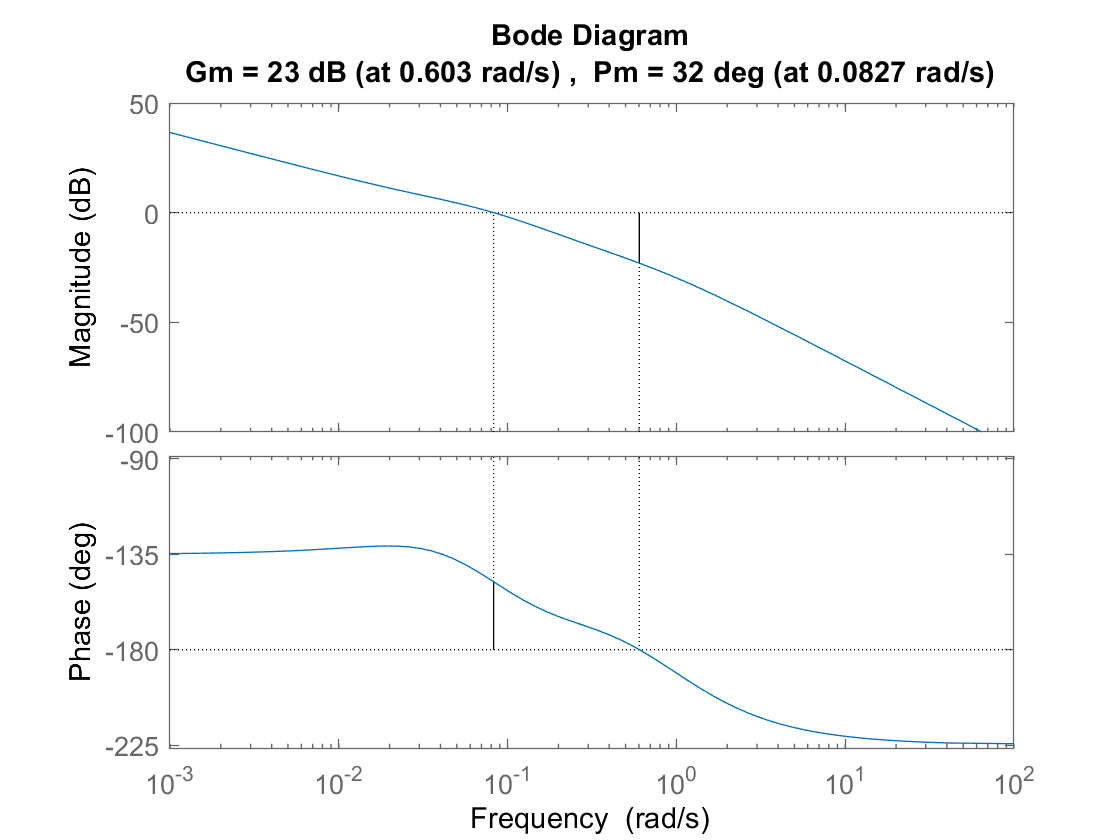


% For finding 45° phase margin gain
margin(sys * -1 * exp(-pi/4 * 1i))

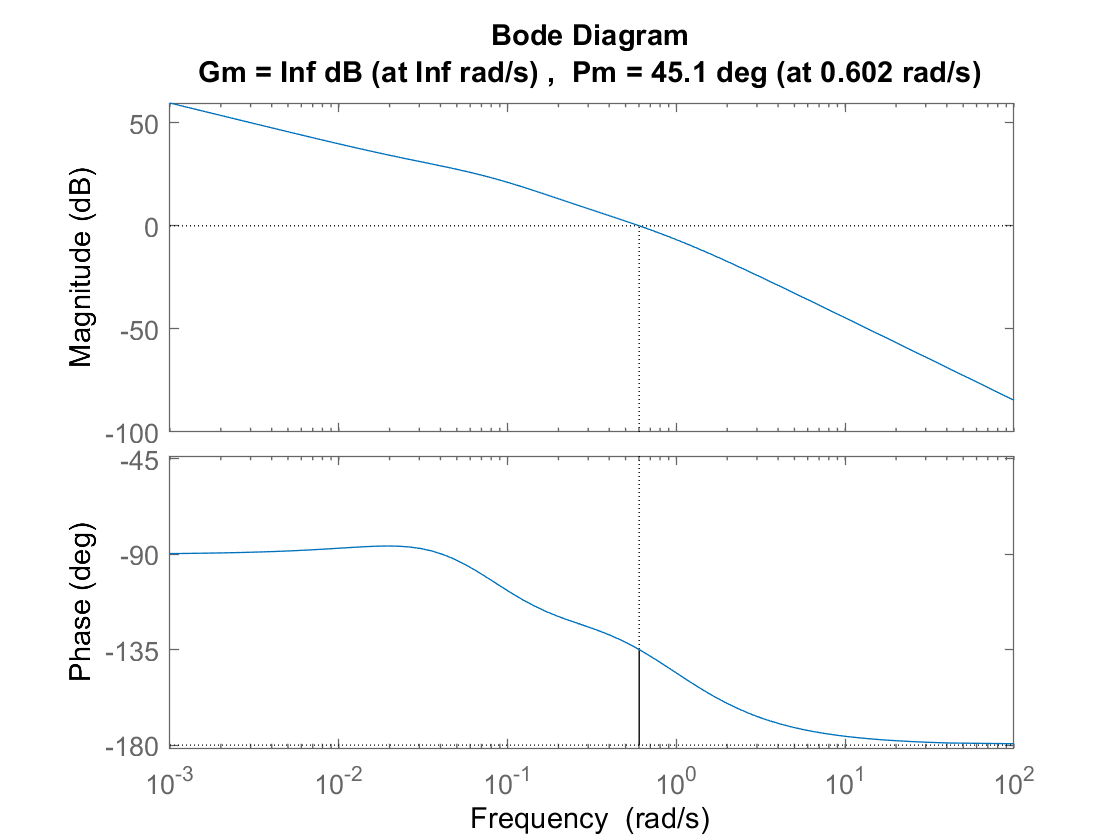

% 45° phase margin controller
margin(sys * -1 * 10^(23/20))

% PI controller
Kp = -1 * 10^(3/20);
Ti = -18.9868;
tf_controller = tf([Kp*Ti, Kp], [Ti, 0])


tf_controller =
 
  -26.82 s + 1.413
  ----------------
      18.99 s
 
Continuous-time transfer function.



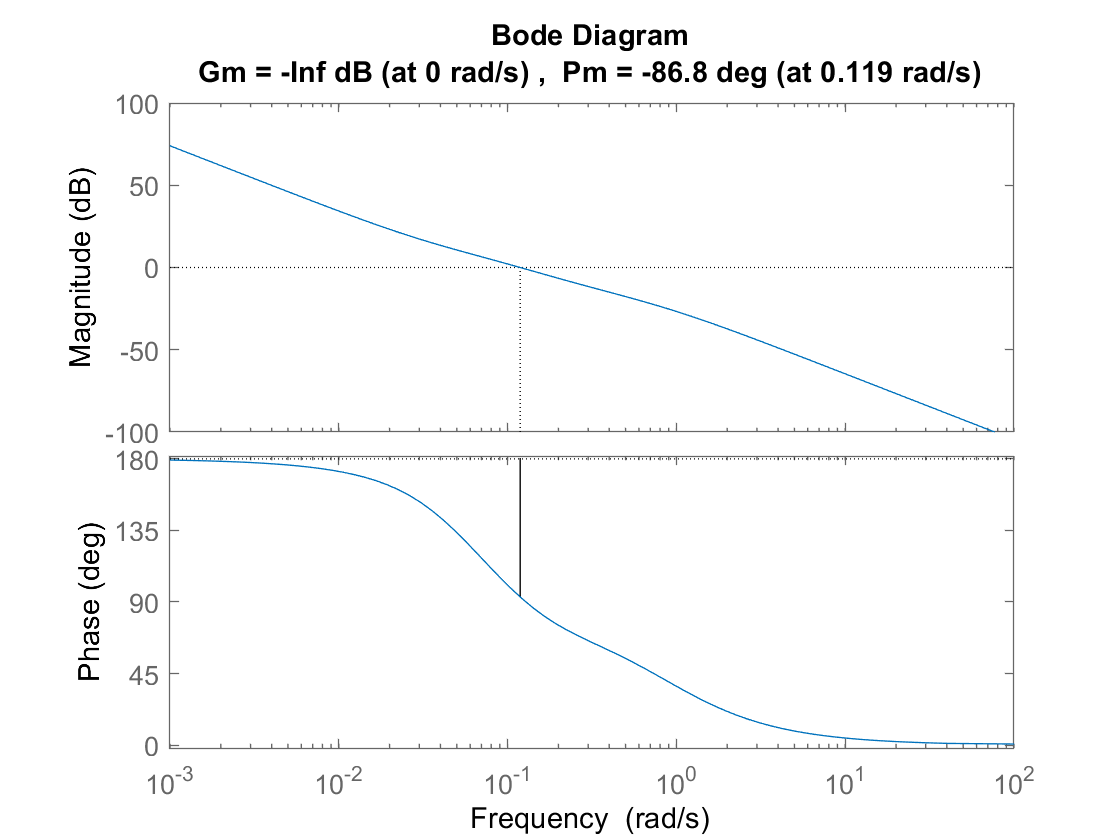


margin(sys * -tf_controller)